# UAV Obstacle Avoidance in Simulink

This model implements waypoint following along with obstacle avoidance on a UAV in a simulated scenario. The model takes a set of waypoints and uses the 3D VFH+ algorithm to provide an obstacle-free path.

## Create UAV Scenario with Custom Lidar Sensor and Obstacles

### Create Scenario

Create a UAV scenario and set its local origin.

Scenario = uavScenario("UpdateRate",100,"ReferenceLocation",[0 0 0]);

Add a marker to indicate the start pose of the UAV.

addMesh(Scenario,"cylinder",{[0 0 1] [0 .01]},[0 1 0]);

### Define UAV Platform

Specify the initial position and orientation of the UAV in the north-east-down (NED) frame.

InitialPosition = [0 0 -7];
InitialOrientation = [0 0 0];

Create a UAV platform in the scenario.

platUAV = uavPlatform("UAV",Scenario, ...
                      "ReferenceFrame","NED", ...
                      "InitialPosition",InitialPosition, ...
                      "InitialOrientation",eul2quat(InitialOrientation));

Add a quadrotor mesh for visualization.

updateMesh(platUAV,"quadrotor",{1.2},[0 0 1],eul2tform([0 0 pi]));

### Create and Mount Sensor Model

Specify the lidar resolution.

AzimuthResolution = 0.5;      
ElevationResolution = 2;

Specify the lidar range.

MaxRange = 7;
AzimuthLimits = [-179 179];
ElevationLimits = [-15 15];

Create a statistical sensor model to generate point clouds for the lidar sensor.

LidarModel = uavLidarPointCloudGenerator("UpdateRate",10, ...
                                         "MaxRange",MaxRange, ...
                                         "RangeAccuracy",3, ...
                                         "AzimuthResolution",AzimuthResolution, ...
                                         "ElevationResolution",ElevationResolution, ...
                                         "AzimuthLimits",AzimuthLimits, ...
                                         "ElevationLimits",ElevationLimits, ...                                       
                                         "HasOrganizedOutput",true);

Create a lidar sensor and mount the sensor on the quadrotor.

uavSensor("Lidar",platUAV,LidarModel, ...
          "MountingLocation",[0 0 -0.4], ...
          "MountingAngles",[0 0 180]);

Preview the scenario using the `show3D` function.

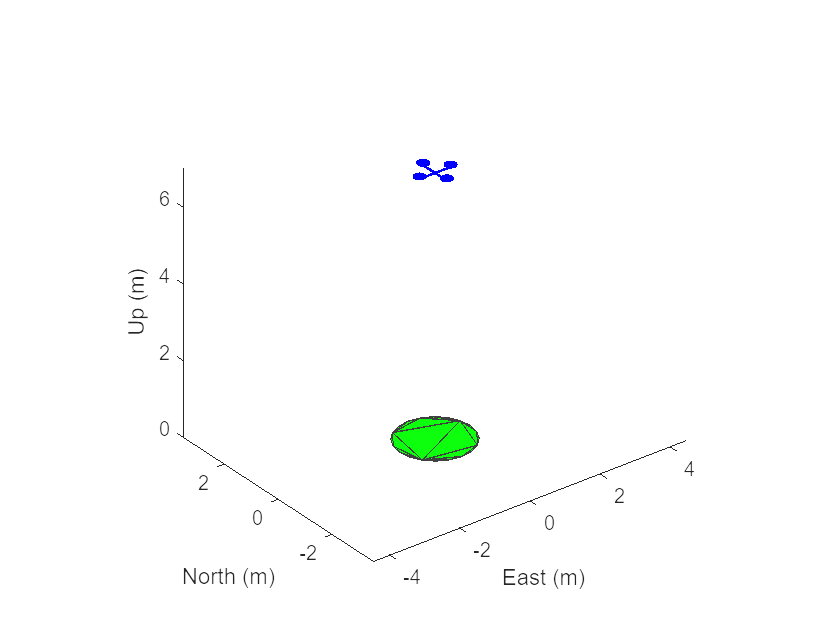

show3D(Scenario);

### Add Obstacles to Scenario

Add cuboid obstacles, representing buildings, to the scenario.

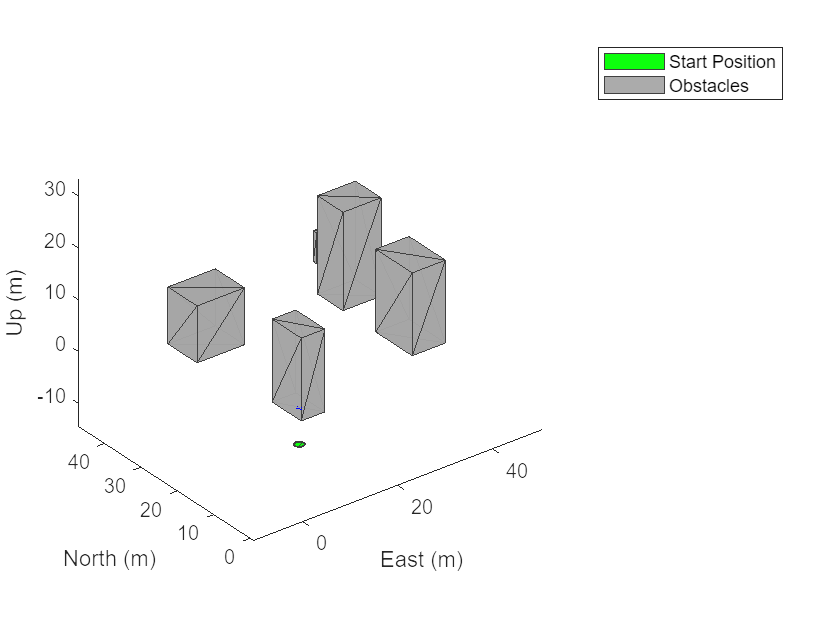

omap3D =  occupancyMap3D;
mapWidth = 50;
mapLength = 50;
numberOfObstacles = randi([3 6],1);
obstacleNumber = 1;
while obstacleNumber <= numberOfObstacles
    width = randi([3 15],1);                 % The largest integer in the sample intervals for obtaining width, length and height                                                     
    length = randi([3 15],1);                % can be changed as necessary to create different occupancy maps.
    height = randi([5 20],1);
    xPosition = randi([0 mapWidth-width],1);
    yPosition = randi([0 mapLength-length],1);
    
    [xObstacle,yObstacle,zObstacle] = meshgrid(xPosition:xPosition+width,yPosition:yPosition+length,0:height);
    xyzObstacles = [xObstacle(:) yObstacle(:) zObstacle(:)];
    
    checkIntersection = false;
    for i = 1:size(xyzObstacles,1)
        if checkOccupancy(omap3D,xyzObstacles(i,:)) == 1
            checkIntersection = true;
            break
        end
    end
    if checkIntersection
        continue
    end
    
    setOccupancy(omap3D,xyzObstacles,1)

    addMesh(Scenario,"polygon", {[xPosition+1 yPosition+1;xPosition+width-1 yPosition+1;xPosition+width-1 yPosition+length-1;xPosition+1 yPosition+length-1],[0 height]},0.651*ones(1,3))
    
    obstacleNumber = obstacleNumber + 1;
end
[xGround,yGround,zGround] = meshgrid(0:mapWidth,0:mapLength,0);
xyzGround = [xGround(:) yGround(:) zGround(:)];
setOccupancy(omap3D,xyzGround,1)

show3D(Scenario);
legend("Start Position","Obstacles")
hold on

## Model Overview

The model consists of these main components:

- `UAV scenario` — Configures the scenario and visualizes the trajectory.

- `Waypoint following and obstacle avoidance` — Implements waypoint following with obstacle avoidance.

- `Controller and plant` — Position controller for the UAV.

- `Control Panel` — Use this panel to enable or disable obstacle avoidance, as well as alter the lookahead distance for obstacle avoidance.

Open the model.

open_system("ObstacleAvoidanceDemo.slx");

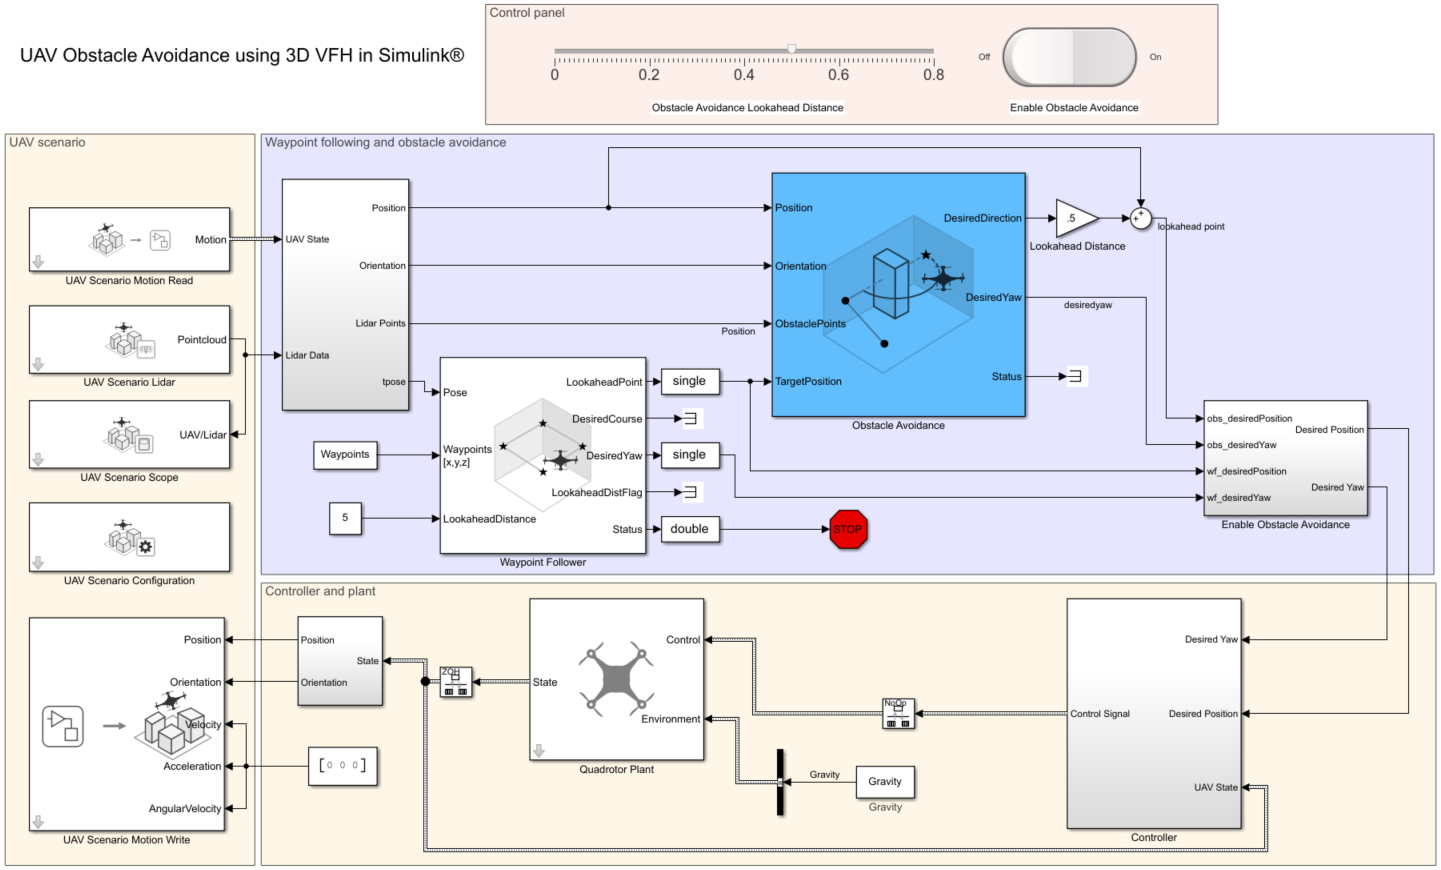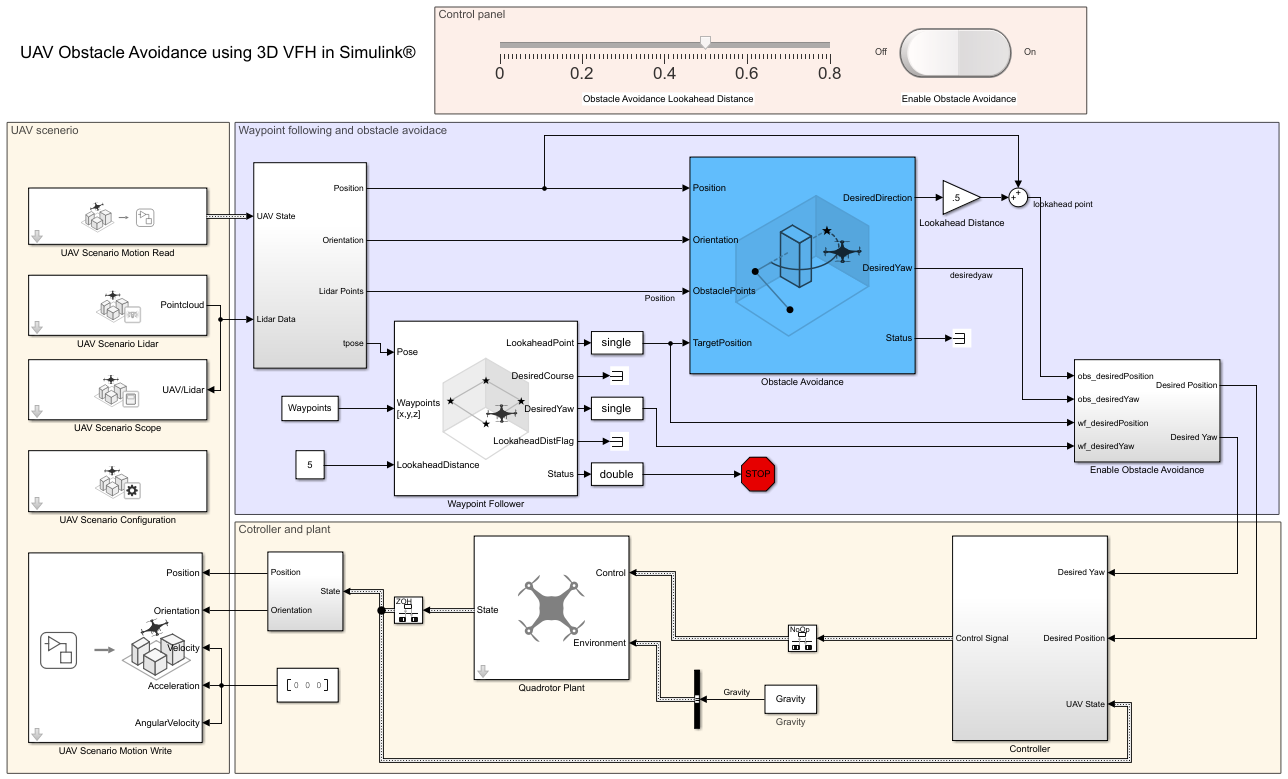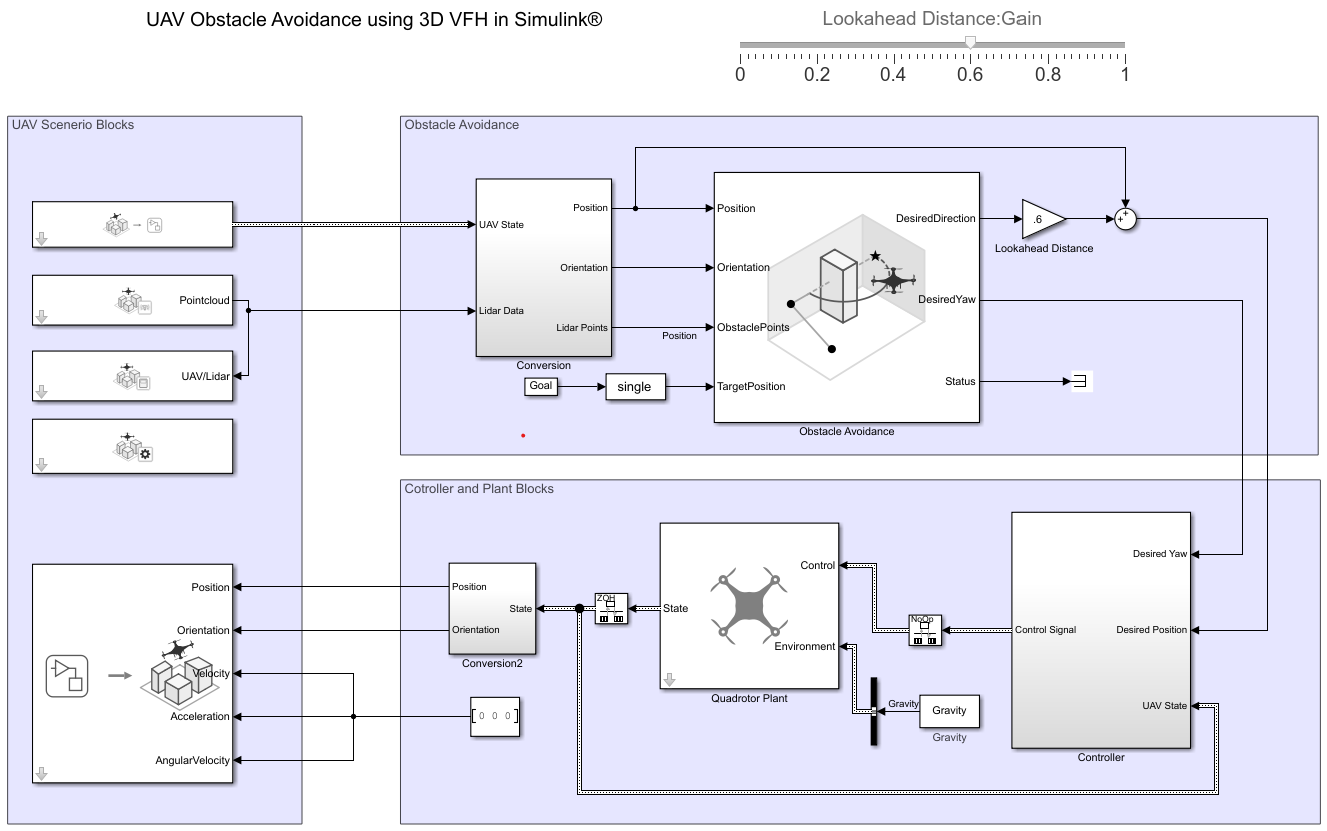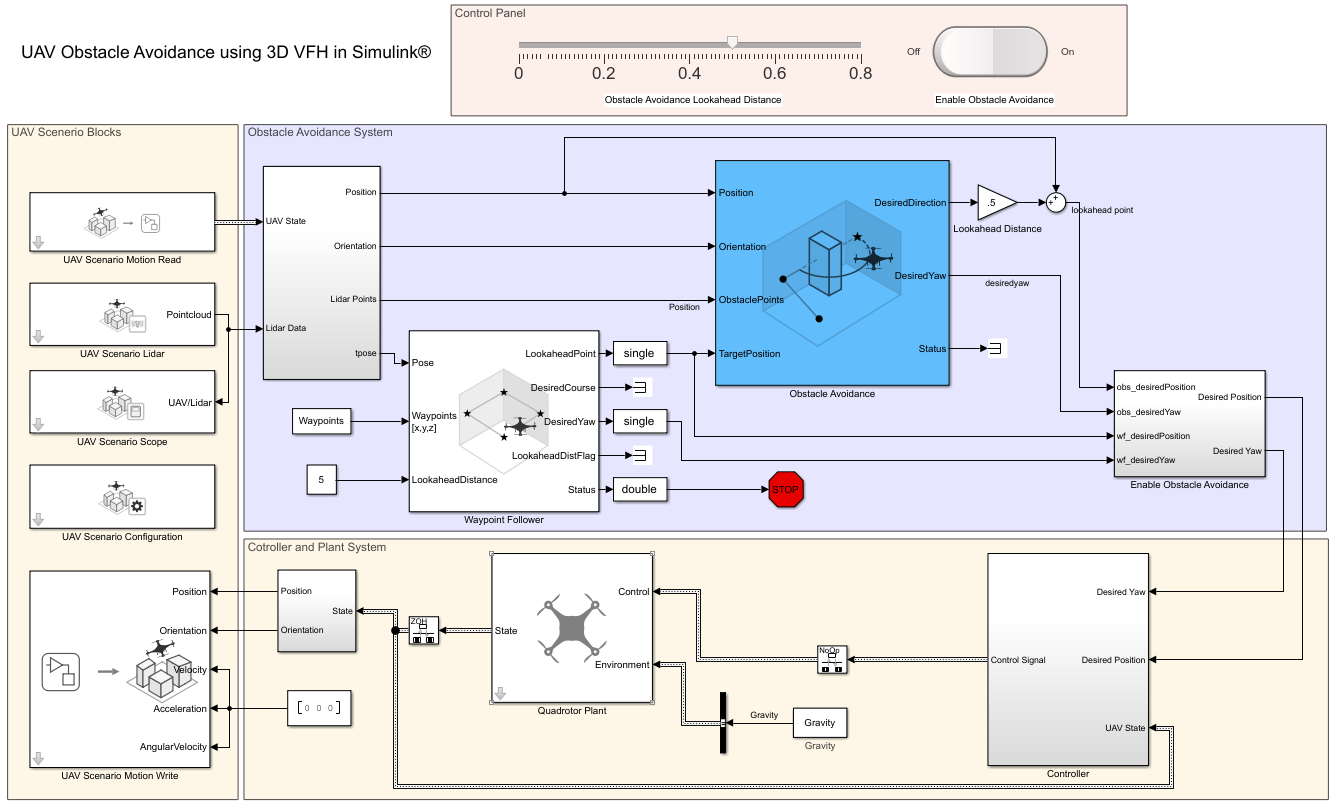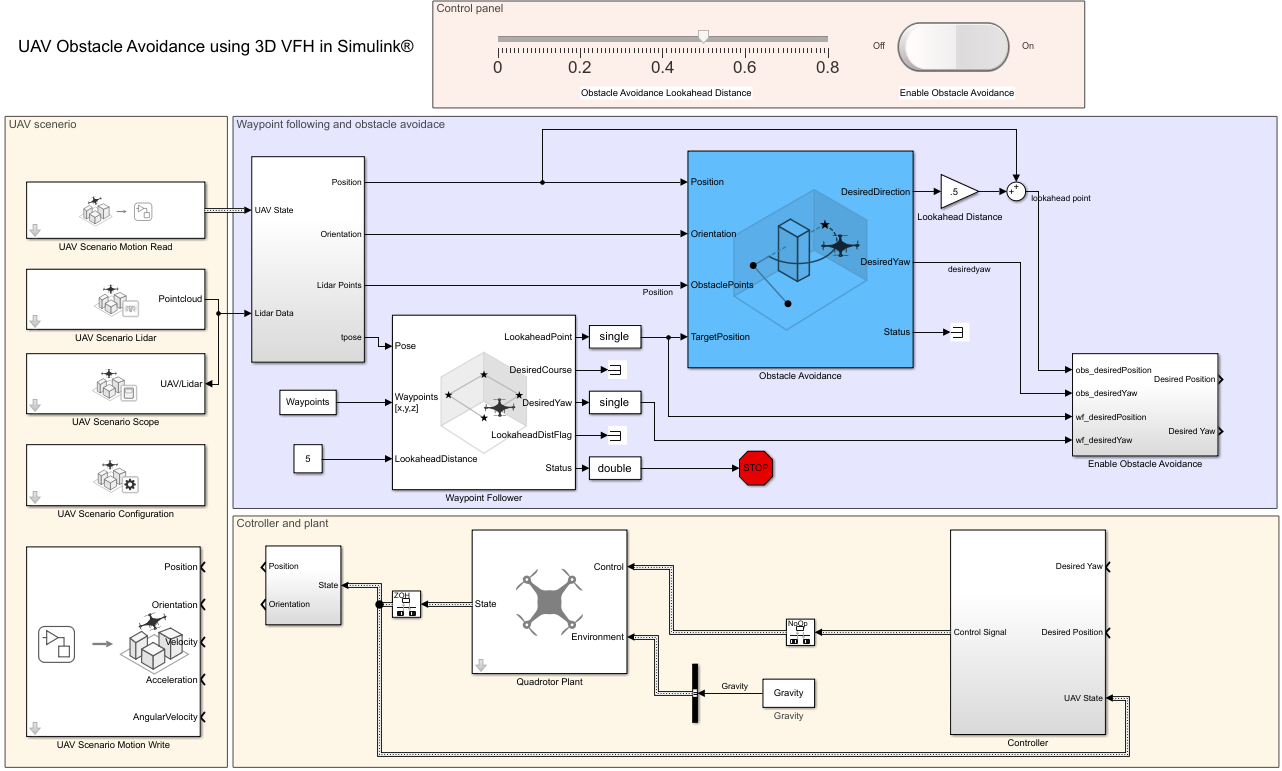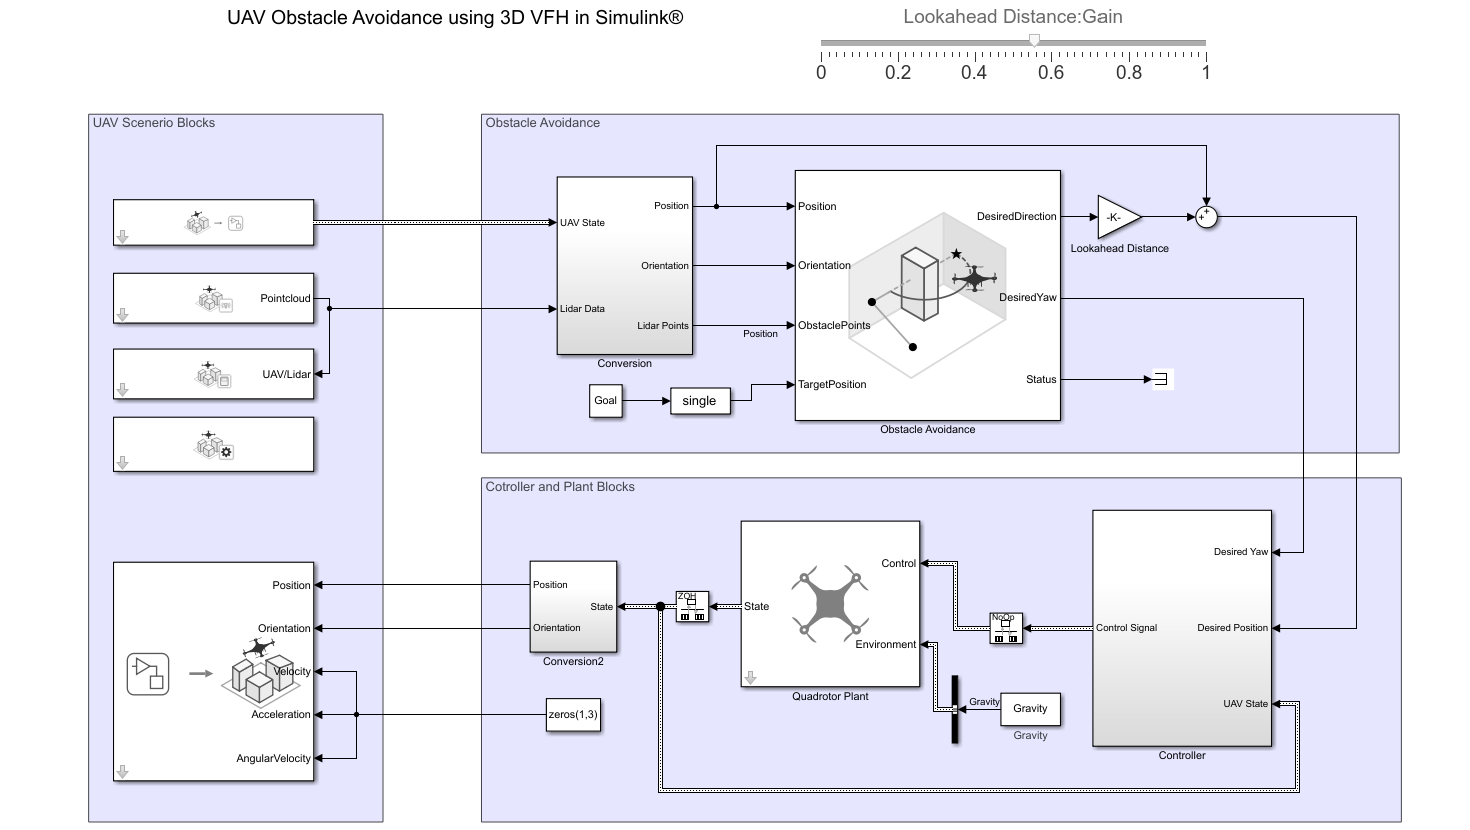

### UAV Scenario

The scenario blocks configure the scenario and visualize the obstacles, trajectory, and the lidar point cloud data.

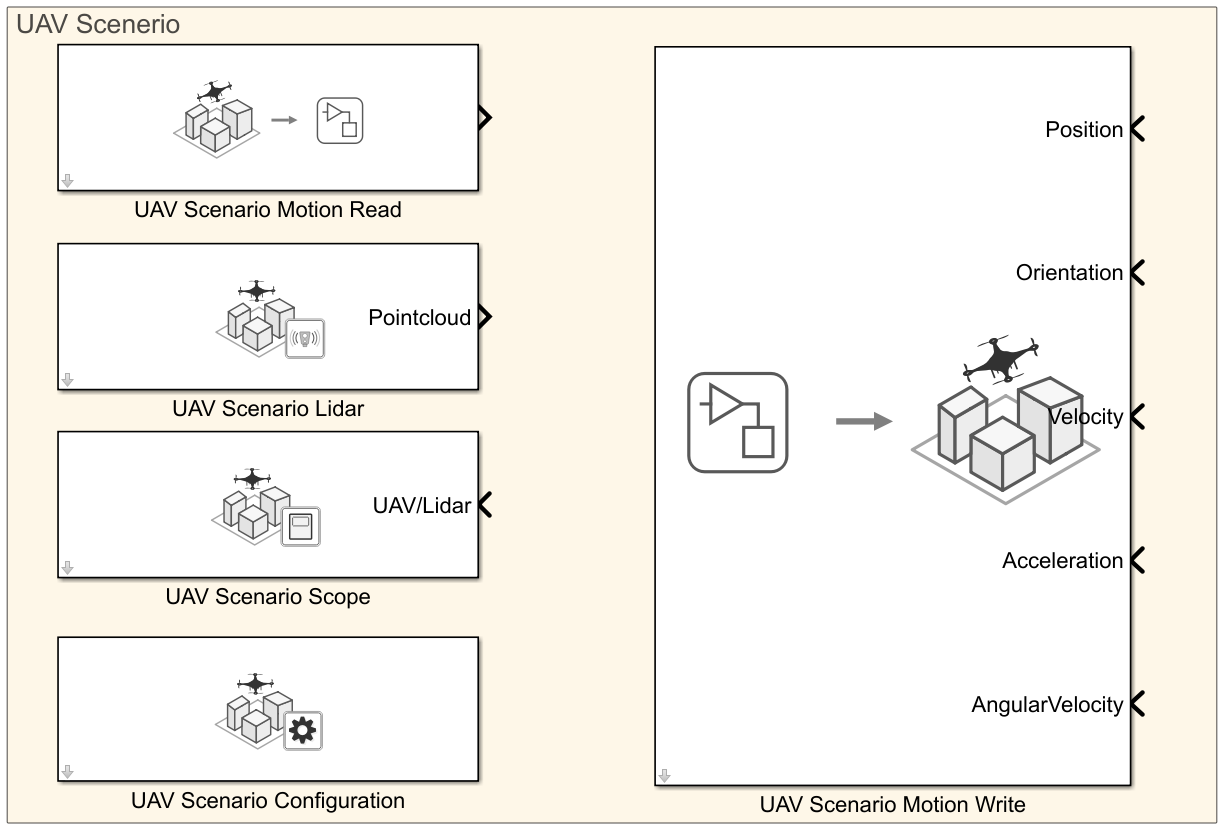

 This subsystem contains these blocks: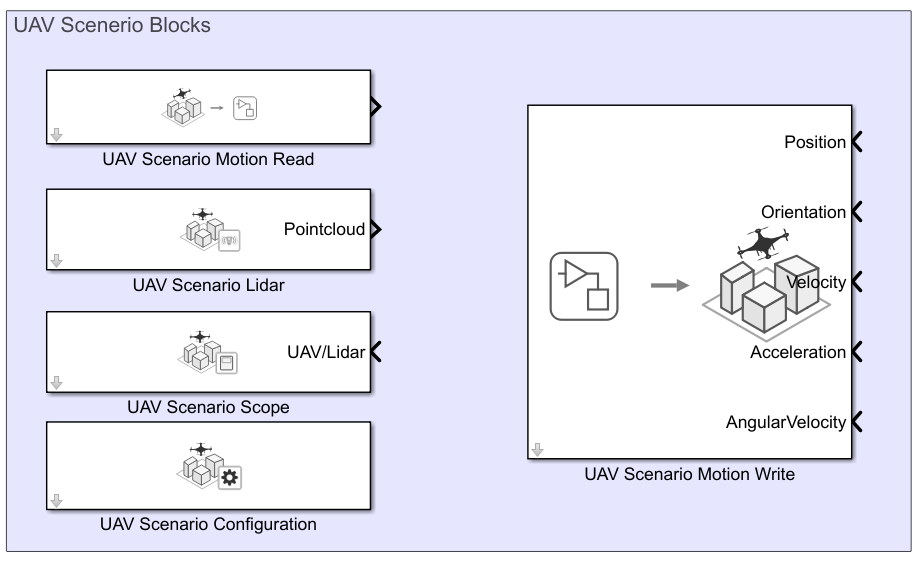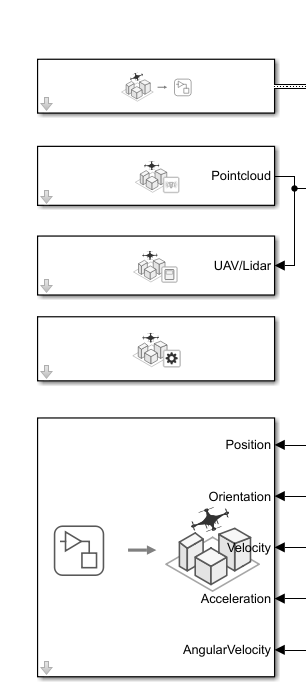

- UAV Scenario Configuration — Configures the scenario blocks to use the generated scenario for simulation.

- UAV Scenario Motion Read — Reads the current UAV state from the scenario.

- UAV Scenario Lidar — Reads the point cloud data from the scenario.

- UAV Scenario Motion Write — Updates the new UAV state.

- UAV Scenario Scope — Visualizes the UAV trajectory and lidar point cloud data.

### Waypoint Following and Obstacle Avoidance

The `Waypoint following and obstacle avoidance` subsystem finds the obstacle-free desired position and the desired yaw according to the current UAV state and point cloud data. 

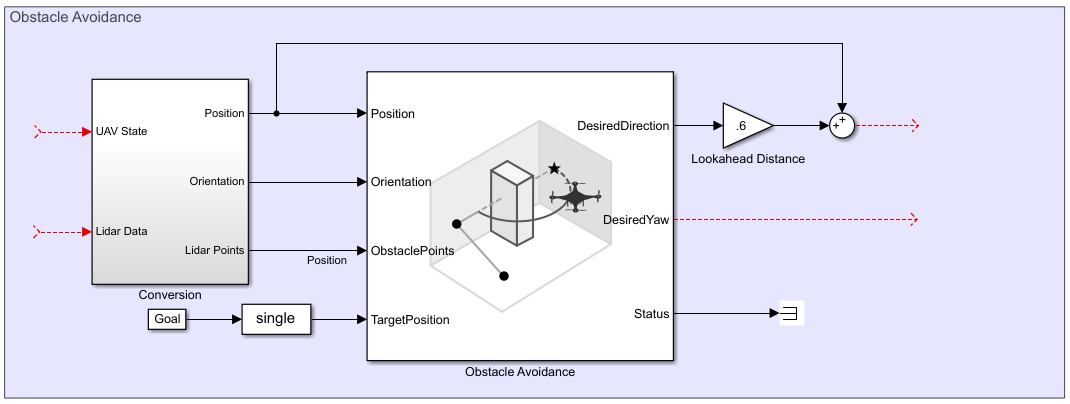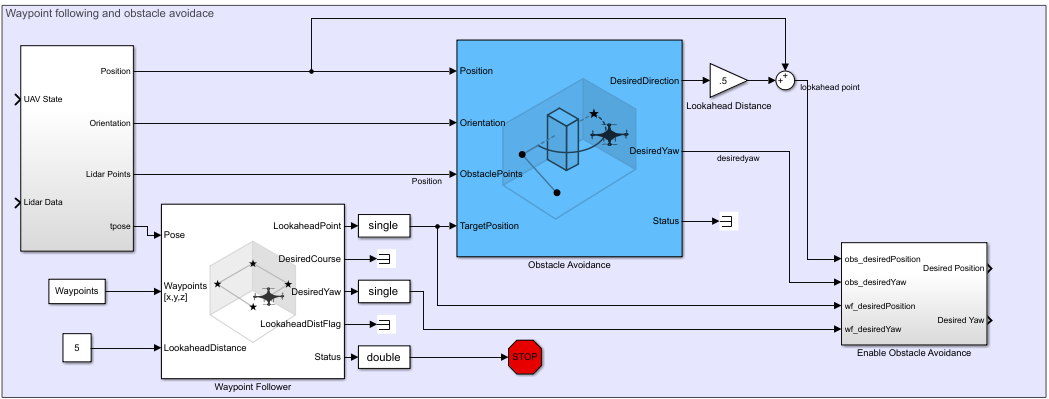

This subsystem includes these blocks and subsystems:

- Waypoint Follower — Computes a lookahead point for the UAV in the direction of the next waypoint.

- Obstacle Avoidance — Uses the 3D VFH+ algorithm to calculate the obstacle-free direction and yaw for a collision-free flight, and updates the lookahead point computed by the Waypoint Follower block.

- Conversion — This subsystem controls the frequency at which obstacle avoidance is used during the flight, and other data type and transform conversions.

- Lookahead Distance — Constant block, the value of which is multiplied by the unit vector in the desired direction, and then added to the current UAV position to compute the desired position.

- Enable Obstacle Avoidance — This subsystem enables or disables obstacle avoidance.

- Waypoints — The set of waypoints through which the UAV is expected to fly.

Specify the waypoints for the UAV.

Waypoints = [InitialPosition];

numberOfWaypoints = randi([3 6],1);
waypointNumber = 1;
while waypointNumber <= numberOfWaypoints
    x = randi([3 45],1);                 % The largest integer in the sample intervals for obtaining width, length and height                                                     
    y = randi([3 45],1);                % can be changed as necessary to create different occupancy maps.
    z = randi([3 25],1);
    [xWP,yWP,zWP] = meshgrid(x-1:x+1,y-1:y+1,z-1:z+1);
    xyzWP = [xWP(:) yWP(:) zWP(:)];
    
    checkIntersection = false;
    for i = 1:size(xyzWP,1)
        if checkOccupancy(omap3D,xyzWP(i,:)) == 1
            checkIntersection = true;
            break
        end
    end
    if checkIntersection
        continue
    end
    
    setOccupancy(omap3D,xyzWP,1)

    addMesh(Scenario,"cylinder",{[x y 1] [z+1 z+1.1]},[1 0 0]);    
    waypointPos = [y x -z];
    Waypoints = vertcat(Waypoints,waypointPos);

    waypointNumber = waypointNumber + 1;
end

Add markers to indicate the waypoints.

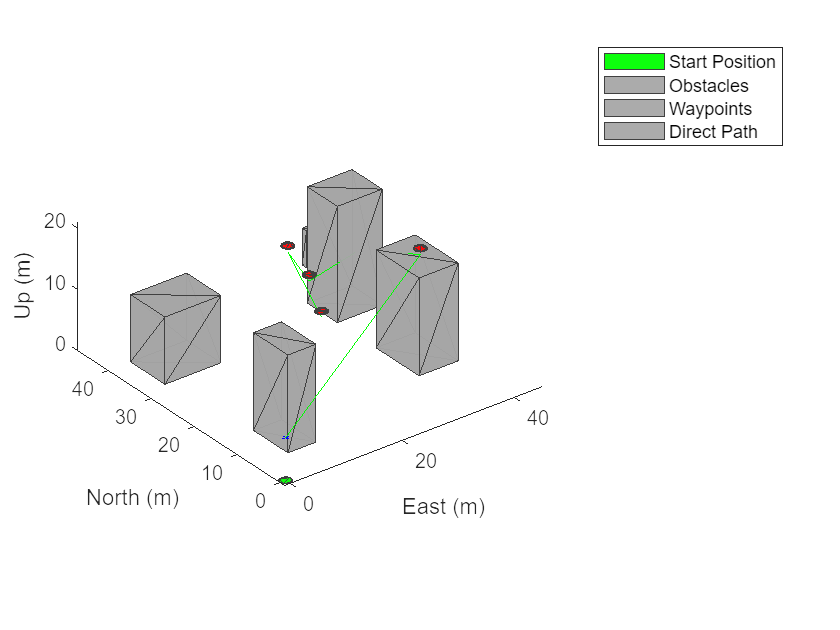

show3D(Scenario);
hold on
plot3([InitialPosition(1,2); Waypoints(:,2)],[InitialPosition(1,2); Waypoints(:,1)],[-InitialPosition(1,3); -Waypoints(:,3)],"-g")
legend(["Start Position","Obstacles","","","Waypoints","","","Direct Path"])

### Controller and plant

The `Controller and plant` subsystem generates the control commands and updates the UAV state based on the lookahead point.

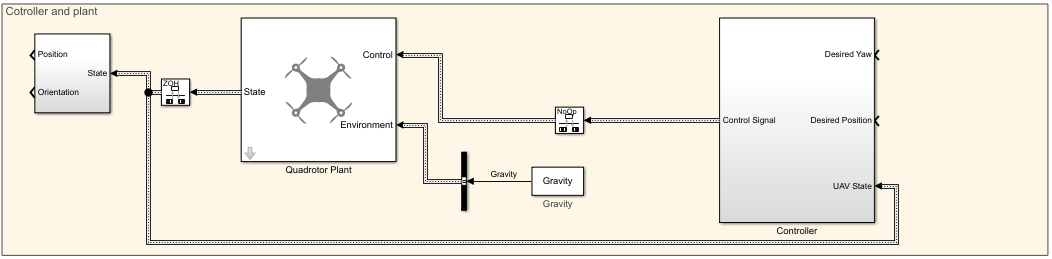 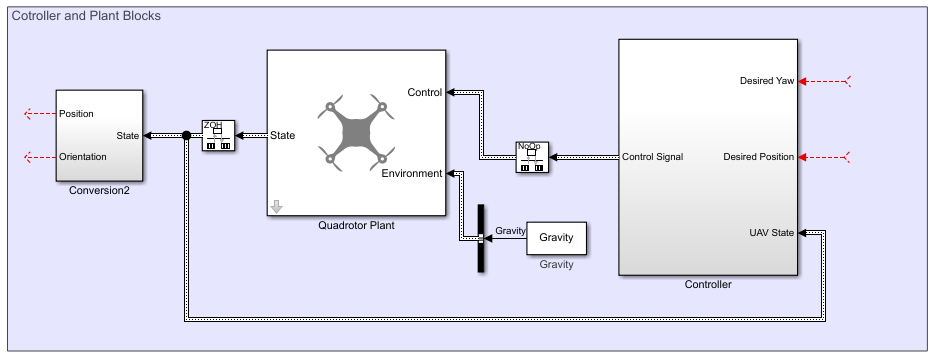

This subsystem includes these blocks:

- `Controller` — This subsystem computes the control commands (roll, pitch, yaw, and thrust) to move the UAV towards the desired position. It uses multiple PID loops to implement position control. 

- `Quadrotor Plant` — This Guidance Model block updates the UAV state using the control commands.

- Conversion — This subsystem extracts the position and orientation from the UAV state, and performs data and coordinate transforms for visualization.

Specify the controller parameters. These parameters are based on a hit-and-trial approach, and can be tuned for a smoother flight.

% Proportional Gains
Px = 6;
Py = 6;
Pz = 6.5;

% Derivative Gains
Dx = 1.5;
Dy = 1.5;
Dz = 2.5;

% Integral Gains
Ix = 0;
Iy = 0;
Iz = 0;

% Filter Coefficients
Nx = 10;
Ny = 10;
Nz = 14.4947065605712; 

 Specify gravity, drone mass, and sample time for the controller and plant blocks.

UAVSampleTime = 0.001;
Gravity = 9.81;
DroneMass = 0.1;

### Control Panel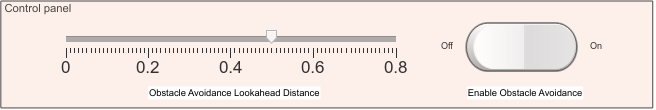

The switch enables or disables the updates to the lookahead point from the Obstacle Avoidance block.

The slider updates the lookahead distance used to compute the lookahead point.

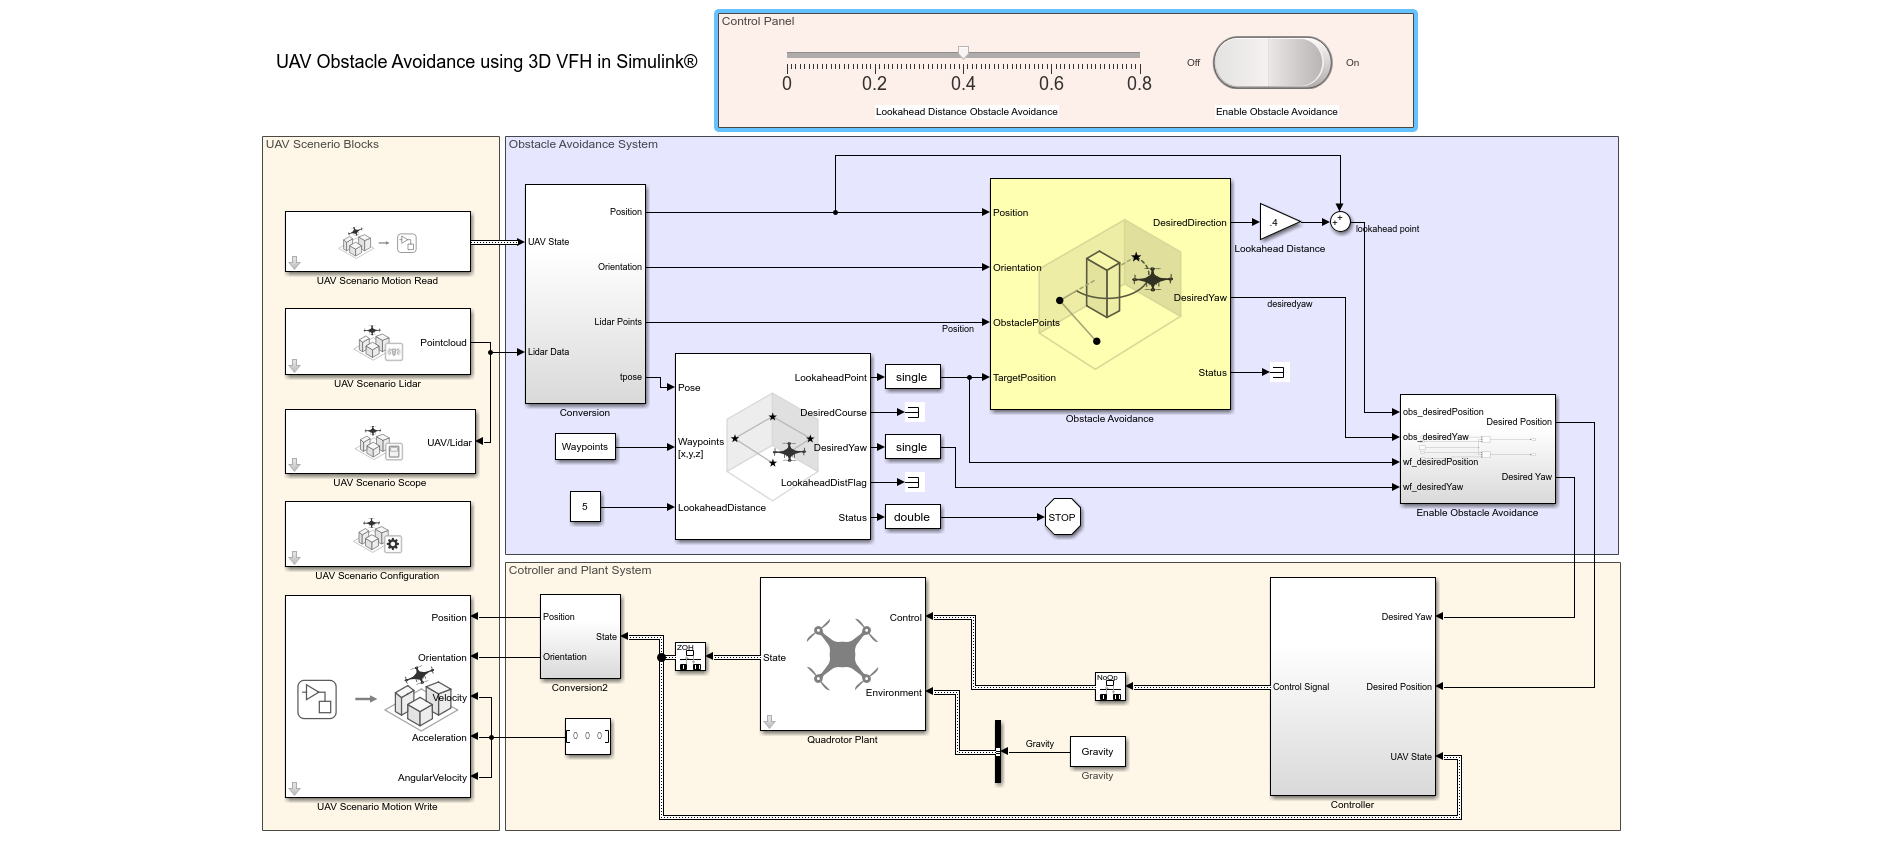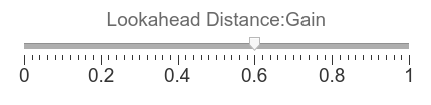

- At greater lookahead distances, UAV flight is faster, but has greater risk of colliding with an obstacle.

- At lower values, the flight is slower, but has a lower risk of colliding with an obstacle. 

## Simulate Model

Configure and run the model, and observe the motion of the UAV.

- The UAV flies through the waypoints while avoiding obstacles, and then the simulation stops.

- Alter the lookahead distance to change the UAV speed.

- Change the parameters of the Obstacle Avoidance block and note the change in the flight path.

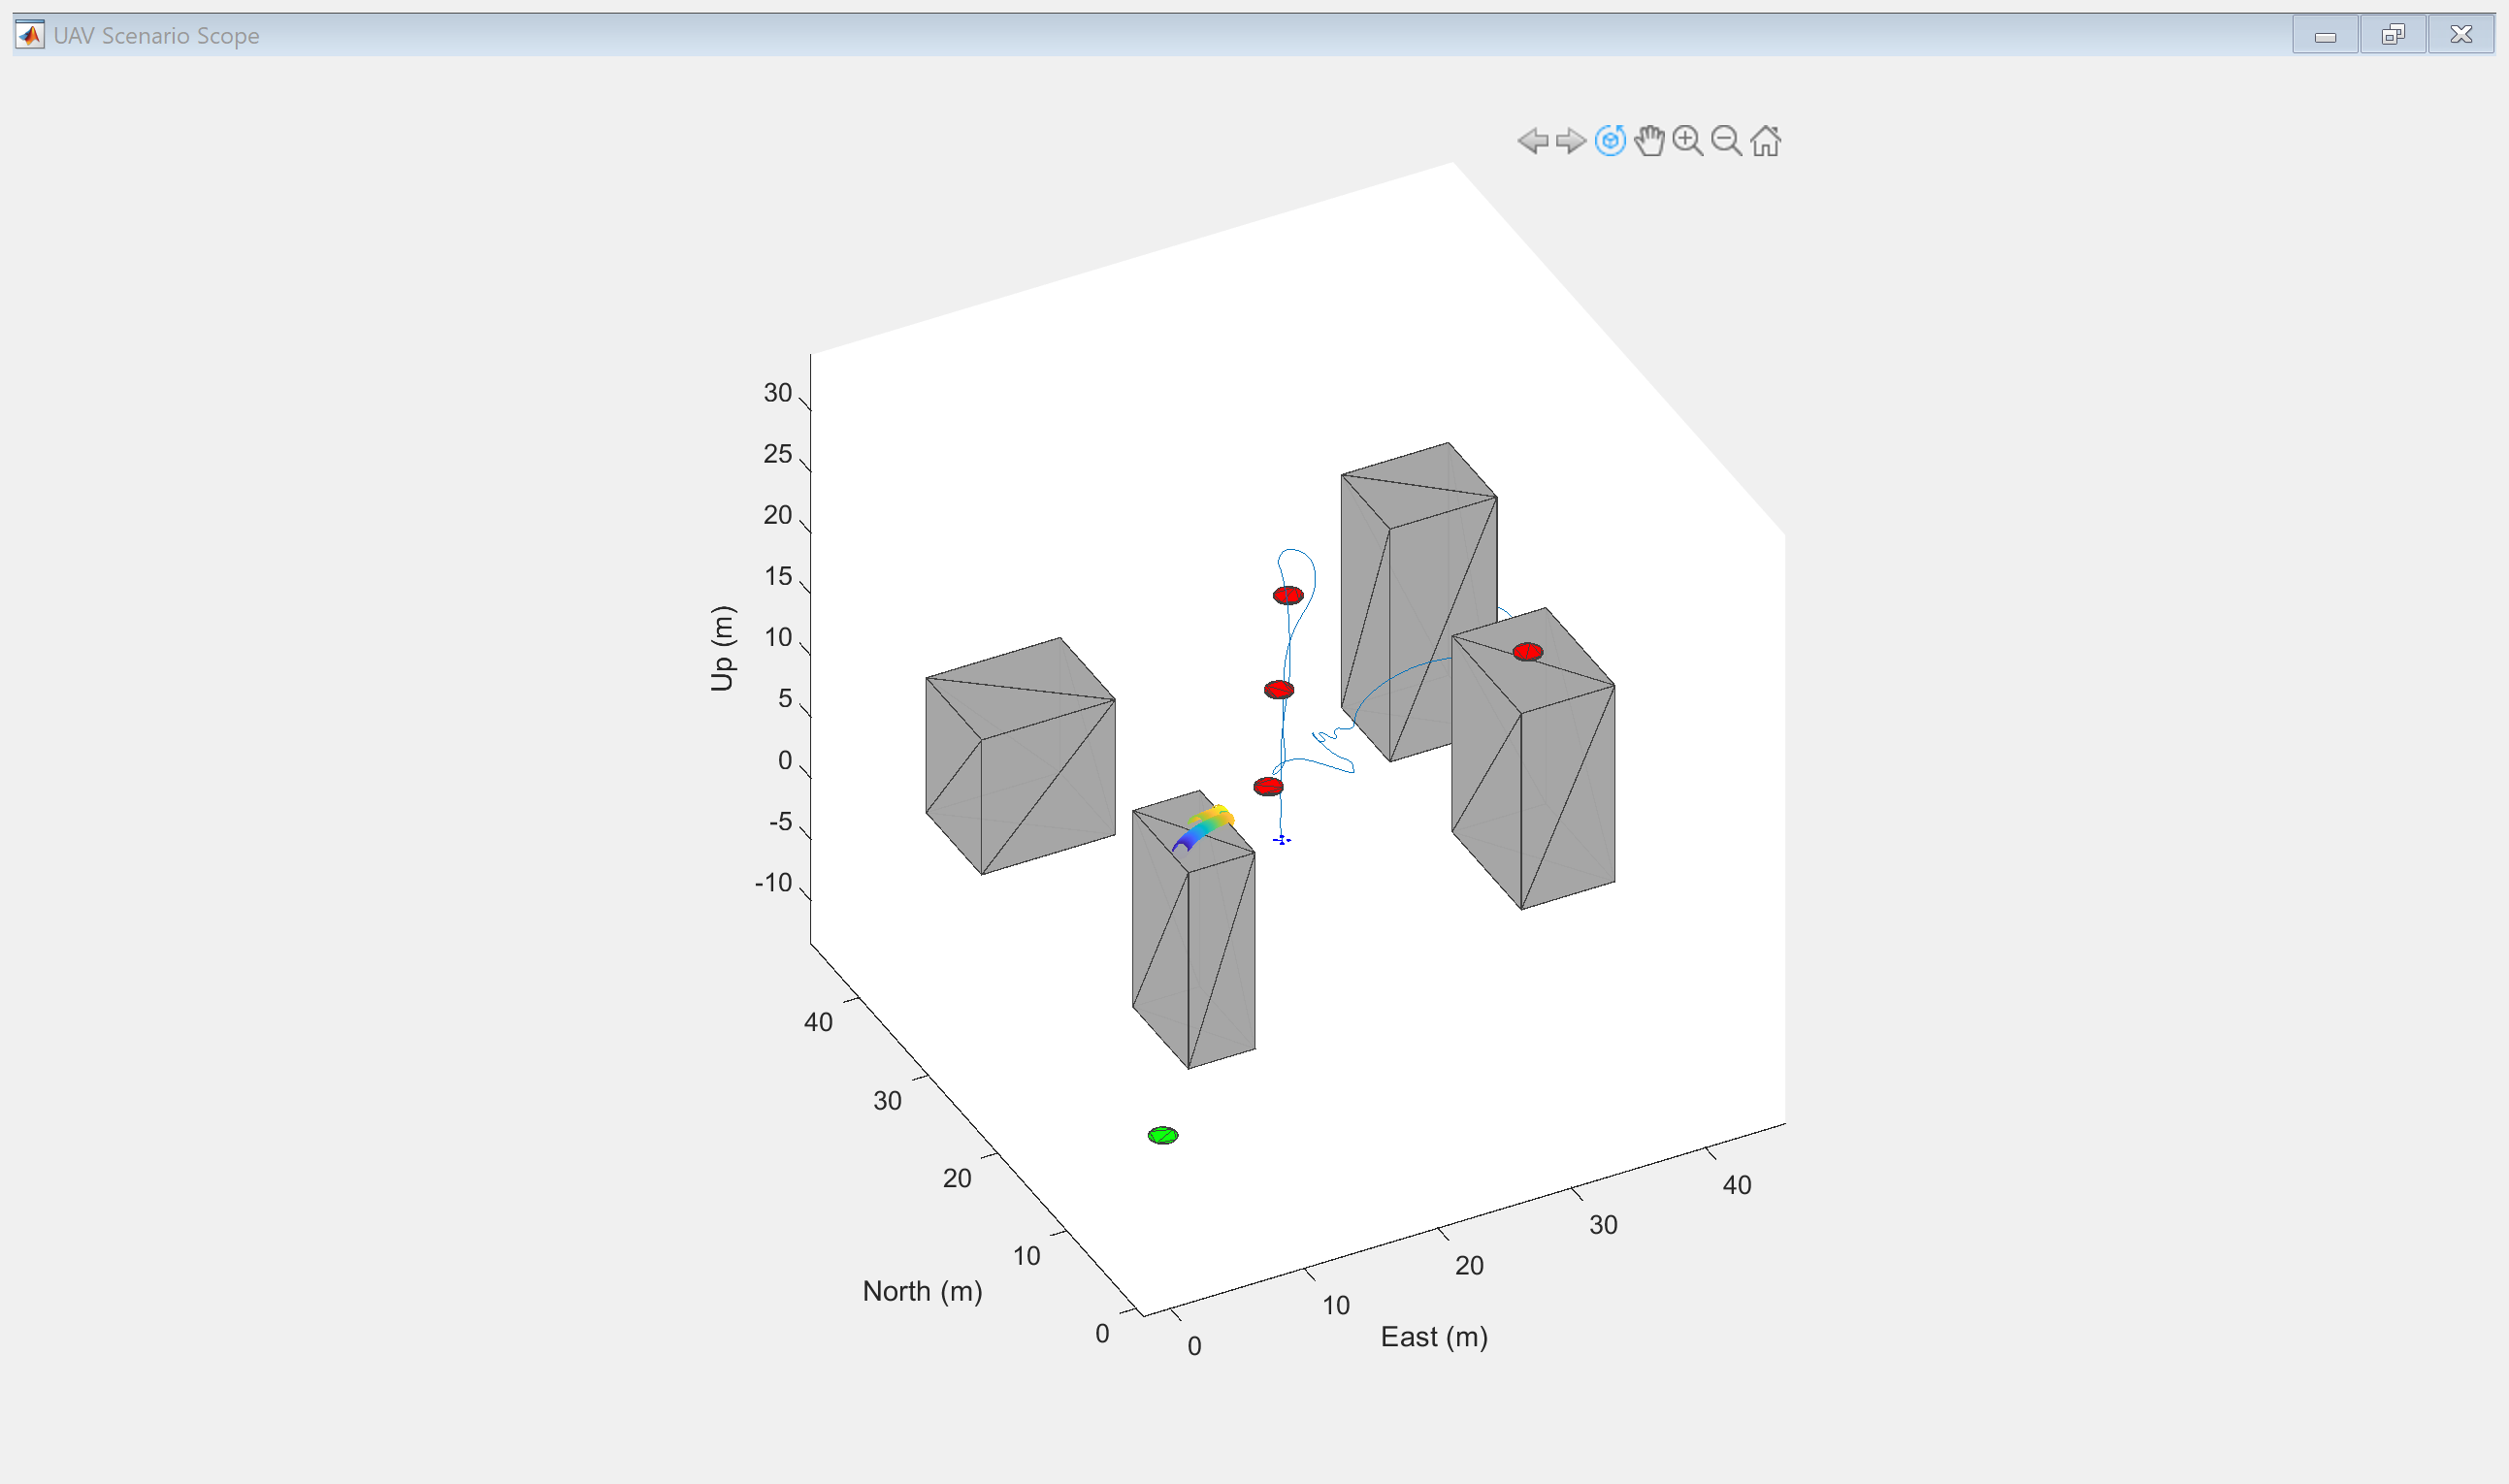

out = sim("ObstacleAvoidanceDemoMPC.slx");

## Visualize Obstacle-Free UAV trajectory

Plot the actual UAV trajectory and the waypoints to show the effect of obstacle avoidance on the UAV flight.

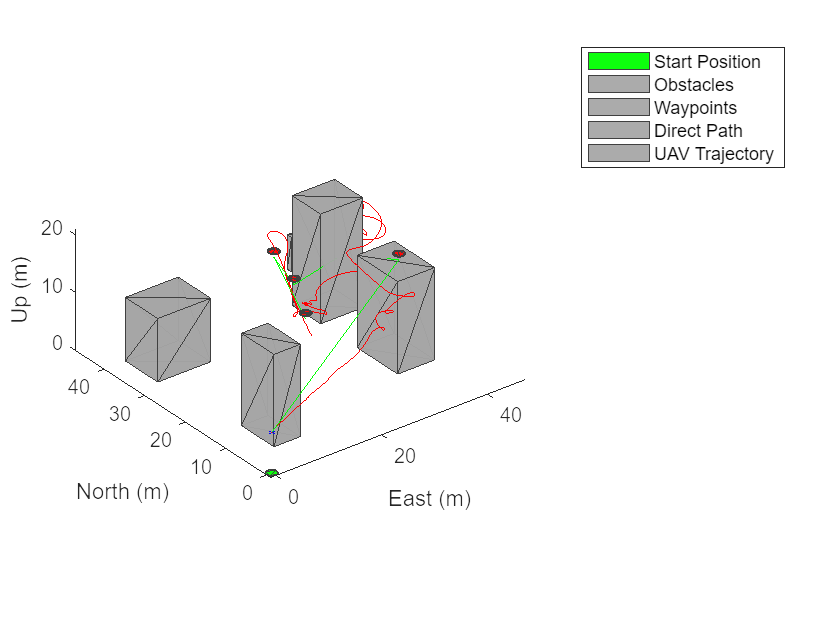

hold on
points = squeeze(out.trajectoryPoints(1,:,:))';
plot3(points(:,2),points(:,1),-points(:,3),"-r");
legend(["Start Position","Obstacles","","","Waypoints","","","Direct Path","UAV Trajectory"])

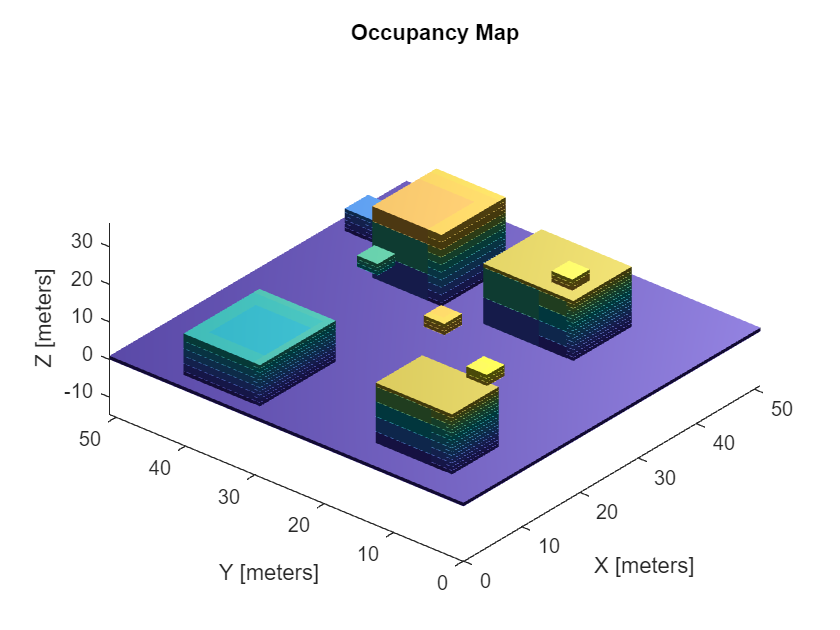

figure("Name","3D Occupancy Map")
show(omap3D)

rollData = timetable2table(ts2timetable(out.simout));
pitchData = timetable2table(ts2timetable(out.simout1));

testData = horzcat(rollData,pitchData(:,2));


writetable(testData,'testing.csv','Delimiter',',','QuoteStrings',true);
type 'testing.csv';

Time,Roll,Pitch
"0 sec",0.07209702,-0.07228513
"0.001 sec",0.07207678,-0.0723053
"0.002 sec",0.07204291,-0.07233904
"0.003 sec",0.07200711,-0.0723747
"0.004 sec",0.071971,-0.07241061
"0.005 sec",0.07193485,-0.07244652
"0.006 sec",0.07189868,-0.07248241
"0.007 sec",0.0718625,-0.07251828
"0.008 sec",0.07182631,-0.07255413
"0.009 sec",0.07179011,-0.07258993
"0.01 sec",0.0717539,-0.07262573
"0.011 sec",0.07171769,-0.07266149
"0.012 sec",0.07168145,-0.07269724
"0.013 sec",0.0716452,-0.07273296
"0.014 sec",0.07160895,-0.07276865
"0.015 sec",0.07157267,-0.07280433
"0.016 sec",0.07153638,-0.07283999
"0.017 sec",0.07150007,-0.07287563
"0.018 sec",0.07146374,-0.07291125
"0.019 sec",0.0714274,-0.07294685
"0.02 sec",0.07139104,-0.07298243
"0.021 sec",0.07135466,-0.073018
"0.022 sec",0.07131825,-0.07305355
"0.023 sec",0.07128184,-0.07308908
"0.024 sec",0.07124539,-0.0731246
"0.025 sec",0.07120894,-0.0731601
"0.026 sec",0.07117245,-0.07319559
"0.027 sec",0.07113596,-0.07323106
"0.028 sec",0.07109943

*Copyright 2021 The MathWorks, Inc.*